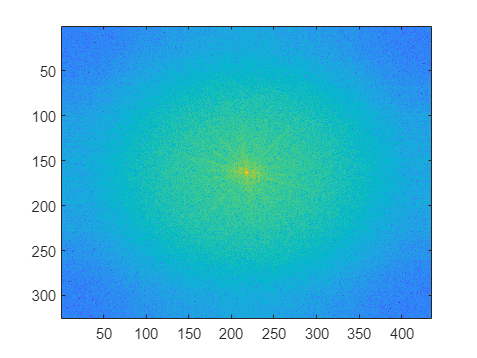

clc;clear;

I = im2double(im2gray(imread("Train/captcha_0325.png")));

fourier = fftshift(fft2(I));
fourier2 = fftshift(fft2(I));
imagesc(log(abs(fourier)))

absFourier = abs(fourier);
maxValue = max(absFourier(:));
thresh_val = 0.01 * maxValue;
mask = absFourier < thresh_val;
fourierFilt = fourier .* mask;
fourier(160,211) = 0;
fourier(157,204) = 0;
fourier(166,225) = 0;
fourier(169,232) = 0;
filteredImage = ifft2(ifftshift(fourier)) + mean2(I);
filteredImage = mat2gray(real(filteredImage));
% crop = filteredImage(1:100, 1:100); imshow(crop); cropHist = imhist(crop);
% J = imgaussfilt(filteredImage,4);
% imshow(J);
X1 = EM_DenoiseTV(filteredImage,0.2);


Iterations:    0, E: 2256.2590 -> 2256.2590                              
Iterations:    1, E: 2256.2590 -> 1700.1475                              
Iterations:    2, E: 2256.2590 -> 1434.5509                              
Iterations:    3, E: 2256.2590 -> 1317.2578                              
Iterations:    4, E: 2256.2590 -> 1224.1952                              
Iterations:    5, E: 2256.2590 -> 1151.6404                              
Iterations:    6, E: 2256.2590 -> 1106.4865                              
Iterations:    7, E: 2256.2590 -> 1075.2735                              
Iterations:    8, E: 2256.2590 -> 1051.0337                              
Iterations:    9, E: 2256.2590 -> 1032.5038                              
Iterations:   10, E: 2256.2590 -> 1017.7543                              
Iterations:   11, E: 2256.2590 -> 1006.0288                              
Iterations:   12, E: 2256.2590 -> 996.1670                              
Iterations:   13, E: 2256.2590 -> 987.

X2 =  histeq(X1);
absJ = abs(X1);
maxValueJ = max(absJ(:));
binaryImage = X2 < 0.09;
original = binaryImage

original = 325×435 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

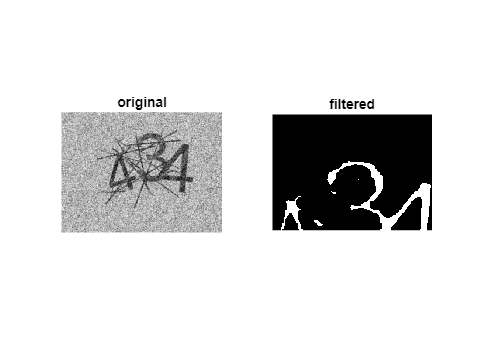

disk = strel("disk",2);
line = strel("line",2,180);
line2 = strel("line",5,90);
% for i = 1:2
%     binaryImage = imerode(binaryImage,SE);
% end
binaryImage = original;
binaryImage = imerode(binaryImage,disk);
binaryImage = imerode(binaryImage,disk);
binaryImage = imerode(binaryImage,line);
binaryImage = imdilate(binaryImage,disk);
binaryImage = imerode(binaryImage,line2);

% Find the bounding box that encapsulates all objects
stats = regionprops(binaryImage, 'BoundingBox');
allBoundingBoxes = cat(1, stats.BoundingBox);

% Get the minimum bounding box that encloses all objects
enclosingBox = [min(allBoundingBoxes(:, 1)), min(allBoundingBoxes(:, 3)), ...
                max(allBoundingBoxes(:, 2)), max(allBoundingBoxes(:, 4))];

% Crop the binary image using the enclosing bounding box
croppedImage = imcrop(binaryImage, enclosingBox);
figure;
subplot(1, 2, 1);
imshow(filteredImage);
title('original');

subplot(1, 2, 2);
imshow(croppedImage);
title('filtered');

%Read in the 5
test2 = imread("Templates\231.jpg")

test2 = 90×106 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     1     1     1     2     2     2     0     0     0     1     1     0     0     0     0     2
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     1     1     1     2     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     0     0     0     0     0     0     1     1     1     0     0     1     1     1     1     0     0     1     0
     0     0     0     0     0     0     0     0     0     0     0   


imagefiles = dir('Templates\*.jpg');      
nfiles = length(imagefiles);    % Number of files found

images = cell(1,nfiles);
for ii=1:nfiles
   currentfilename = imagefiles(ii).name;
   currentimage = imread(currentfilename);
   images{1,ii} = currentimage;
end 
%Rotate it
% test2 = imrotate(test2,-30)
%Call cross correlation matching in fourier domain
% out =templatematch(binaryImage*255,test2);
% %Draw the template
% template  = test2;
background = croppedImage*255;
% %crop background
% bx = size(background, 2); 
% by = size(background, 1);
% tx = size(template, 2);
% ty = size(template, 1);

%% display best match
% hFig = figure;
% hAx  = axes;
% position = [x, y, tx, ty];
% imshow(background);
% drawrectangle('Position',position);
% templates=[test2]
% rotations=[0,10,20,30,-10,-20,-30]
%for template in templates:
%    for rotation in rotation:



max_values = zeros(1,3);
max_digit = cell(1,3);


for i = 1:nfiles
    correlation_map = templatematch(background,images{1,i});
    correlation_regions=split_correlation_map(correlation_map,3);
    for j =1:3
        current_max = max(correlation_regions(:,:,j),[],'all');
        if(current_max > max_values(1,j))
            max_values(1,j)= current_max;
            digit{1,j} = images{1,i};
        end
    end
end
topKRows = maxk(max_values, 3, 1);  % Top k elements along each column
top_3 = maxk(topKRows, 1, 2);  % Top k elements along each row

% Iterate over 3,4,5 for different scales and rotations
    % Compute top 3 region of matches (To catch 333,444,555 etc)
% Take top 3 matches out of all matches and thats the prediction